help c2d % About command 'c2d'

 c2d  Converts continuous-time dynamic system to discrete time.
 
    SYSD = c2d(SYSC,TS,METHOD) computes a discrete-time model SYSD with
    sample time TS that approximates the continuous-time model SYSC.
    The string METHOD selects the discretization method among the following:
       'zoh'           Zero-order hold on the inputs
       'foh'           Linear interpolation of inputs
       'impulse'       Impulse-invariant discretization
       'tustin'        Bilinear (Tustin) approximation.
       'matched'       Matched pole-zero method (for SISO systems only).
       'least-squares' Least-squares minimization of the error between
                       frequency responses of the continuous and discrete
                       systems (for SISO systems only).
       'damped'        Damped Tustin approximation based on TRBDF2 formula
                       (sparse models only).
    The default is 'zoh' when METHOD is omitted. The sample time TS s

help tf % About command 'tf'

 tf  Construct transfer function or convert to transfer function.
 
   Construction:
     SYS = tf(NUM,DEN) creates a continuous-time transfer function SYS with
     numerator NUM and denominator DEN. SYS is an object of type tf when
     NUM,DEN are numeric arrays, of type GENSS when NUM,DEN depend on tunable
     parameters (see REALP and GENMAT), and of type USS when NUM,DEN are
     uncertain (requires Robust Control Toolbox).
 
     SYS = tf(NUM,DEN,TS) creates a discrete-time transfer function with
     sample time TS (set TS=-1 if the sample time is undetermined).
 
     S = tf('s') specifies the transfer function H(s) = s (Laplace variable).
     Z = tf('z',TS) specifies H(z) = z with sample time TS.
     You can then specify transfer functions directly as expressions in S
     or Z, for example,
        s = tf('s');  H = exp(-s)*(s+1)/(s^2+3*s+1)
 
     SYS = tf

clear % Clears workspace
DT = 0.01 % Discrete time interval is 2ms

DT = 0.0100

order = 1 % Assume the system is first order

order = 1

ns = 1.42; % Transfer function numerator coefficients
ds = [10.9 1 1.42]; % Transfer function denominator coefficients
as = tf(ns,ds) % Build transfer function in 's' domain

as =
 
         1.42
  -------------------
  10.9 s^2 + s + 1.42
 
Continuous-time transfer function.
Model Properties


zbi = c2d(as,DT,'tustin') % from 's' to 'z' domain tf using bilinear transformation

zbi =
 
  3.255e-06 z^2 + 6.511e-06 z + 3.255e-06
  ---------------------------------------
          z^2 - 1.999 z + 0.9991
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


zfh = c2d(as,DT,'foh') % same but using first order hold

zfh =
 
  2.171e-06 z^2 + 8.681e-06 z + 2.17e-06
  --------------------------------------
          z^2 - 1.999 z + 0.9991
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


zzh = c2d(as,DT,'zoh') % using zero order hold, default if not defined

zzh =
 
  6.512e-06 z + 6.51e-06
  ----------------------
  z^2 - 1.999 z + 0.9991
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


help step % About step command

 step  Step response of dynamic systems.
 
    step computes the response to a step change in input value from U to
    U+DU after TD time units. The start time t0, final time tF, step
    delay TD, baseline input U, and step amplitude DU are all adjustable
    with defaults t0=0, U=0, DU=1, TD=0. You can also specify the initial
    state x(t0). When you don't, the system is assumed to be initially at
    rest with input level U.
 
    [Y,T] = step(SYS) computes the step response Y of the dynamic system SYS.
    The time vector T is expressed in the time units of SYS and the time
    step and final time are chosen automatically. For multi-input systems,
    independent step commands are applied to each input channel. If SYS has
    NY outputs and NU inputs, Y is an array of size [NUMEL(T) NY NU] where
    Y(:,:,j) contains the step response of the j-th input channel.
 
    [Y,T] = step(SYS,TFINAL) simulates the step r

T = 0:DT:0.04 % Creating x-axis from 0 to 0.04 in interval of DT

T =          0    0.0100    0.0200    0.0300    0.0400


[ylp, tm] = step(as,T) % 's' tf

ylp = 1.0e-03 *

         0
    0.0065
    0.0260
    0.0586
    0.1041


tm =          0
    0.0100
    0.0200
    0.0300
    0.0400


[ybi] = step(zbi,T) % Similarly others, plot data storing in matrix

ybi = 1.0e-03 *

    0.0033
    0.0163
    0.0423
    0.0813
    0.1333


[yfh] = step(zfh,T)

yfh = 1.0e-03 *

    0.0022
    0.0152
    0.0412
    0.0802
    0.1323


[yzh] = step(zzh,T)

yzh = 1.0e-03 *

         0
    0.0065
    0.0260
    0.0586
    0.1041


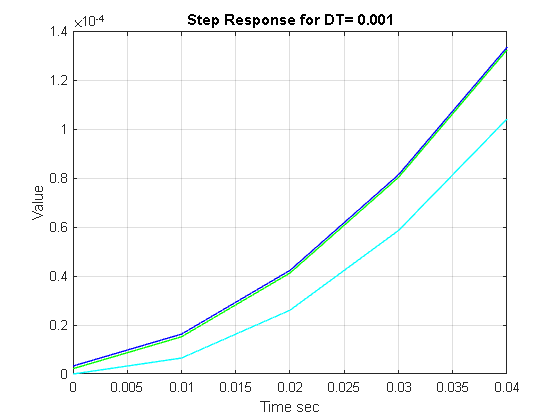

plot(tm,ylp,'r',tm, ybi, 'b', tm, yfh, 'g', tm, yzh, 'c')
grid
title('Step Response for DT= 0.001')
xlabel('Time sec')
ylabel('Value')

% For frequency response, can directly use 'bode' command to plot
% https://www.mathworks.com/help/ident/ref/dynamicsystem.bode.html
help bode

 bode  Bode frequency response of dynamic systems.
 
    bode(SYS) draws the Bode plot of the dynamic system SYS. The frequency 
    range and number of points are chosen automatically.
 
    bode(SYS,{WMIN,WMAX}) draws the Bode plot for frequencies between WMIN 
    and WMAX in radians/TimeUnit (relative to the time units specified in 
    SYS.TimeUnit, the default being seconds).
 
    bode(SYS,W) uses the vector W of frequencies (in radians/TimeUnit) to
    evaluate the frequency response. See LOGSPACE to generate logarithmically 
    spaced frequency vectors.
 
    bode(SYS1,SYS2,...,W) graphs the Bode response of several systems
    SYS1,SYS2,... on a single plot. The frequency vector W is optional. 
    You can specify a color, line style, and marker for each model, for
    example:
       bode(sys1,'r',sys2,'y--',sys3,'gx').
 
    [MAG,PHASE] = bode(SYS,W) and [MAG,PHASE,W] = <s

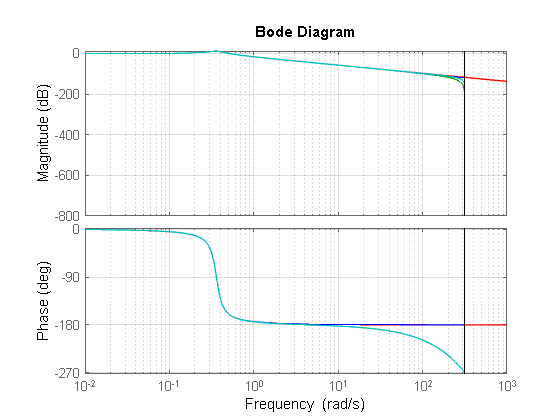

bode(as,'r', zbi, 'g', zfh, 'b', zzh, 'c')
grid